fig = figure();
set(fig,'Visible','on');


colobj = roomspec();
robot=robotspec([0.4 0.2 0.2]);
%roomshow(colobj)
resolution = 100;
binary_map = colobj2binary_map(colobj, resolution);

show(binary_map);
view(-90,90);
%axis equal

global buttons
buttons = struct('W', false, 'A', false, 'S', false, 'D', false)

buttons = struct with fields:
    W: 0
    A: 0
    S: 0
    D: 0


fig.KeyPressFcn = @KeyPressFcn;
fig.KeyReleaseFcn = @KeyReleaseFcn;

rateObj = rateControl(15);
n = 0;

THETA_DOT_MAX = 2;
X_DOT_MAX = 1;

THETA_DOT_DOT = 2;
X_DOT_DOT = 2;

anchor_mat = [ 0 10 10  0
               0  0 10 10
               3  3  3  3]

anchor_mat =      0    10    10     0
     0     0    10    10
     3     3     3     3


p_tag_front = [0.2; 0]

p_tag_front =     0.2000
         0


p_tag_back = [-0.2; 0]

p_tag_back =    -0.2000
         0



theta_dot_cmd = 0;
x_dot_cmd = 0;
cmd_history = []


cmd_history =

     []





lidar = rangeSensor("HorizontalAngleResolution", 2*pi/50);
lidar_history = [];

odom_history = []; 
IMU_history = [];
utrue_prev = [0;0];
dist_front_history = [];
dist_back_history = [];

robot_state = [1; 1; 0];
robot_state_history = [];

hold on
robot_plot = plot([0 0 0 0 0], [0 0 0 0 0], 'k')

robot_plot =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0 0 0]
              YData: [0 0 0 0 0]
              ZData: [1×0 double]

  Show all properties


hold off
update_robot_plot(robot_plot, robot_state);

RCC = room_cover_controller();

LK = localization_kalman()

LK =   localization_kalman with properties:

           state: [6×1 double]
             cov: [6×6 double]
     p_tag_front: []
      p_tag_back: []
      anchor_mat: []
               T: []
     UWB_cov_mat: []
     IMU_cov_mat: []
    odom_cov_mat: []
     process_cov: []



LK.T = 1/15;
LK.p_tag_front = [0.2; 0];
LK.p_tag_back  = [-0.2; 0];
LK.anchor_mat = [ 0 10 10  0
               0  0 10 10
               3  3  3  3];
LK.odom_cov_mat = eye(2)*0.1.^2;
LK.UWB_cov_mat = eye(8)*0.1.^2;
LK.IMU_cov_mat = eye(2)*0.1.^2;
LK.process_cov = diag([0 0 0 0.2 0.2 1]).^2;

while ishghandle(fig) % Stop loop when window closes
    n = n+1;   
    

    % Set velocity goal based on WASD buttons and QE buttons
%     theta_dot_goal = buttons2velocity_goal(buttons.D, buttons.A, THETA_DOT_MAX);
%     x_dot_goal = buttons2velocity_goal(buttons.S, buttons.W, X_DOT_MAX);
    %[x_dot_goal, theta_dot_goal] = RCC.step(robot_state, ranges, angles);
    [x_dot_goal, theta_dot_goal] = RCC.step(LK.state(1:3), ranges, angles);
    
    % Update desired velocities to pursue velocity goals 
    if abs(theta_dot_cmd-theta_dot_goal) < THETA_DOT_DOT*rateObj.DesiredPeriod
        theta_dot_cmd = theta_dot_goal;
    else
        theta_dot_cmd = theta_dot_cmd + sign(theta_dot_goal-theta_dot_cmd)*THETA_DOT_DOT*rateObj.DesiredPeriod;
    end

    if abs(x_dot_cmd-theta_dot_goal) < X_DOT_DOT*rateObj.DesiredPeriod
        x_dot_cmd = x_dot_goal;
    else
        x_dot_cmd = x_dot_cmd + sign(x_dot_goal-x_dot_cmd)*X_DOT_DOT*rateObj.DesiredPeriod;
    end

    cmd = [x_dot_cmd; theta_dot_cmd];

    [robot_state,utrue] = robot_model(robot_state,cmd,rateObj.DesiredPeriod,[0.2; 0.2]);
    
    update_robot_plot(robot_plot, robot_state);

    drawnow limitrate

    robot_state_history(:,n) = robot_state;
    cmd_history(:,n) = cmd;
    odom_history(:,n) = utrue + normrnd([0;0],[0.1; 0.1]);
    IMU_history(:,n) = [ (utrue(1)-utrue_prev(1))/rateObj.DesiredPeriod; utrue(2)] + normrnd([0;0],[0.1; 0.1]);
    utrue_prev = utrue;
    
    [ranges,angles] = lidar(robot_state',binary_map);
    lidar_history(:,n) = ranges;

    
    dist_vec_front = uwb_model(robot_state, p_tag_front, anchor_mat)' + normrnd([0;0;0;0],[1;1;1;1]*10e-2);
    dist_vec_back = uwb_model(robot_state, p_tag_back, anchor_mat)' + normrnd([0;0;0;0],[1;1;1;1]*10e-2);

    dist_front_history(:,n) = dist_vec_front;
    dist_back_history(:,n) = dist_vec_back;

    [state_c, cov_c] = LK.multi_meas([dist_vec_front; dist_vec_back], IMU_history(:,n), odom_history(:,n));

    %waitfor(rateObj);
end

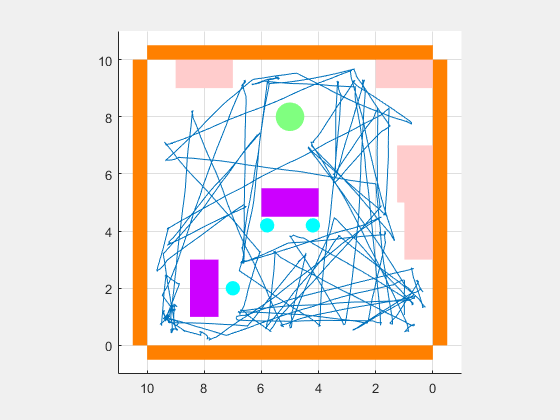


fig = figure();
set(fig,'Visible','on');
hold on
roomshow(colobj)

plot(robot_state_history(1,:), robot_state_history(2,:))

hold off
axis square

function KeyPressFcn(src, event)
global buttons
    %disp(event.Key);
    switch event.Key
        case 'w'; buttons.W = true;
        case 'a'; buttons.A = true;
        case 's'; buttons.S = true;
        case 'd'; buttons.D = true;
    end
end

function KeyReleaseFcn(src, event)
global buttons
    %disp(event.Key);
    switch event.Key
        case 'w'; buttons.W = false;
        case 'a'; buttons.A = false;
        case 's'; buttons.S = false;
        case 'd'; buttons.D = false;
    end
end

function velocity_goal = buttons2velocity_goal(button_min, button_max, velocity_magnitude)
    if(button_min && ~button_max)
        velocity_goal = -velocity_magnitude;
    elseif (button_max && ~button_min)
        velocity_goal = velocity_magnitude;
    else
        velocity_goal = 0;
    end
end

function update_robot_plot(robot_plot, robot_state)
d_x = 0.4;
d_y = 0.2;

x_0 = [-d_x d_x d_x -d_x -d_x NaN d_x 2*d_x]/2;
y_0 = [-d_y -d_y d_y d_y -d_y NaN 0 0]/2;

xy = rot2(robot_state(3)) * [x_0; y_0] + robot_state(1:2);


set(robot_plot, "XData", xy(1,:), "YData", xy(2,:));

end